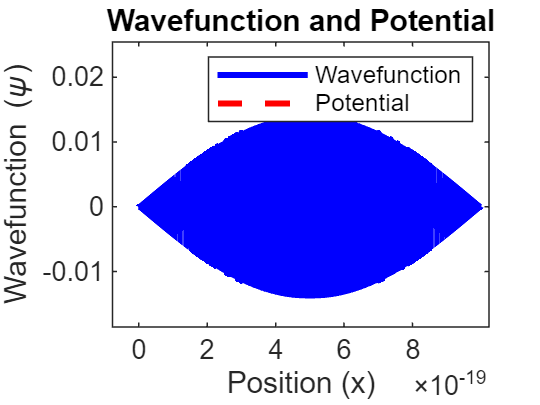

% Define parameters
hbar = 1;     % Reduced Planck constant (arbitrary units)
m = 1;        % Electron mass (arbitrary units)
L = 1e-18;        % Length of the semiconductor region
N = 10000;     % Number of grid points
dx = L / N;   % Grid spacing

% Define the Hamiltonian matrix H
H = zeros(N, N);
for i = 1:N
    H(i, i) = -2 / (m * dx^2) + potential(i * dx);
    if i > 1
        H(i, i - 1) = 1 / (m * dx^2);
    end
    if i < N
        H(i, i + 1) = 1 / (m * dx^2);
    end
end


% Solve the eigenvalue problem
[psi, E] = eig(H);

% Plot the wavefunction and potential
xValues = linspace(0, L, N);
plot(xValues, psi(:, 1), 'b', 'LineWidth', 2);
hold on;
plot(xValues, potential(xValues), 'r--', 'LineWidth', 2);
xlabel('Position (x)');
ylabel('Wavefunction (\psi)');
legend('Wavefunction', 'Potential');
title('Wavefunction and Potential');

Define potential function V(x) (arbitrary units)

function V = potential(x)
    % Define your potential function here
    a0 = 5.29177210903e-11;
    V=(1/sqrt(pi))*((1/a0)^(3/2))*exp(x/a0);
    % For simplicity, let's assume a constant potential
    V = 0;
end